# First-Order Backward Differentiator

This live script is for use with the textbook

*Discrete-Time Signals and Systems: A MATLAB Integrated Approach*

by O. Alkin, CRC Press, 2025.

It is based on the discussion in Example 8.12 of the text. Let $x_{a}(t)$ be an analog sinusoidal signal in the form


$$x_{a}(t)=\sin(2\pi f_{0}t)$$


which is sampled with a sampling rate of $f_{s}=200$ Hz, and processed using a first-order backward difference filter. We would like to compute and graph the steady-state differentiator output against the actual derivative of $x_{a}(t)$.

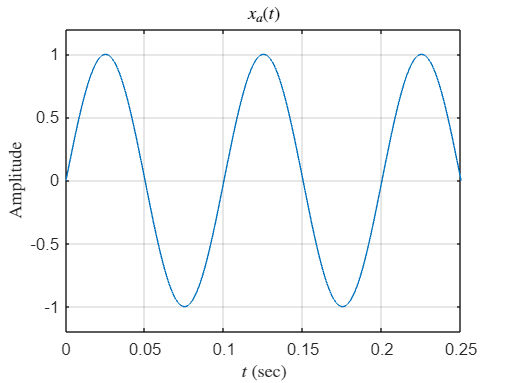

f0 = 10; % Frequency of the signal
fs = 200;  % Sampling rate
% Compute and graph the analog signal
t = [0:0.001:0.25];
xa = sin(2*pi*f0*t);
plot(t,xa); grid;
axis([0,0.25,-1.2,1.2]);
set(0,'defaultTextInterpreter','latex');
xlabel('$t$ (sec)');
ylabel('Amplitude');
title('$x_{a}(t)$');

The system function of the first-order backward differentiator is


$$H(z)=\frac{f_{s}(z-1)}{z}$$


Compute the value of the system function at the appropriate angular frequency. The steady state value of the differentiator output is


$$$\hat{y}(t)=|H(\Omega_{0}|\sin(2\pi f_{0}t+\angle H(\Omega_{0}))$$


and the actual derivative of $x_{a}(t)$ is


$$y_{a}(t)=2\pi f_{0}\cos(2\pi f_{0}t)$$


F0 = f0/fs;
Omg0 = 2*pi*F0;
[HMag,HPhs] = ss_freqz([1],[0],fs,Omg0)

HMag = 62.5738

HPhs = 1.4137

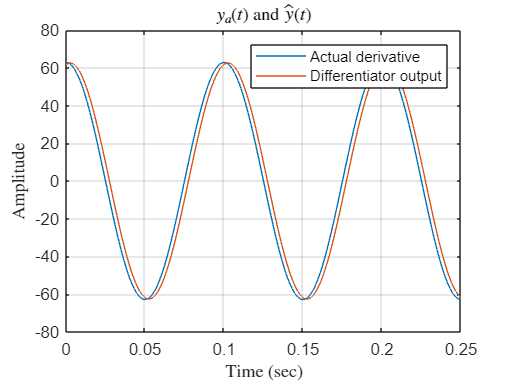

yhat = HMag*sin(2*pi*f0*t+HPhs);
y = 2*pi*f0*cos(2*pi*f0*t);
plot(t,y,t,yhat); grid;
%axis([0,0.25,-100,100]);
xlabel('$t$ (sec)');
ylabel('Amplitude');
title('$y_{a}(t)$ and $\hat{y}(t)$');
xlabel('Time (sec)');
ylabel('Amplitude');
legend('Actual derivative','Differentiator output');

set(0,'defaultTextInterpreter','tex');